clear, close all, clc


1.

die_vals = [1 2 3 4 5 6];
num_dies = 2;

num_side_die = length(die_vals);


Prob_snakeeye = (1/num_side_die)^2

Prob_snakeeye = 0.0278


num_sevens = 0;
for k = 1:length(die_vals)
    die1_val = die_vals(k);
    for j = 1:length(die_vals)
        die2_val = die_vals(j);
    if die1_val + die2_val == 4
        num_sevens = num_sevens + 1;
    end
    end
end

Prob_sevens = num_sevens/(num_side_die^num_dies)

Prob_sevens = 0.0833


Ratio_probs = Prob_sevens/Prob_snakeeye

Ratio_probs = 3

2. Analytic Proof


$$P_{A+B}(x)=\int_{}^{}P_{A}(z)P_{b}(x-z)\,dz=P_{A}(x)*P_{B}(x)$$


Lets take the same example from above but lets use the number of fours we are able to get. We can get 4 by either adding 1 and 3, 2 and 2, and 3 and 1.


$$P_{1}(x) = \frac{1}{6}, P_{2}(x) = \frac{1}{6}, P_{3}(x) = \frac{1}{6}$$


Lets substitute in the numbers and since we are dealing with die which have only 6 distinct possibilities wee can use the summation operator rather then the integrator operator.


$$P_{1+3}(x)=\sum_{n=1}^{4}P_{1}(n)P_{3}(x-n)$$



$$P_{1+3}(x) = P_{3}(4-1)P_{1}(1)+P_{3}(4-2)P_{1}(2)+P_{3}(4-3)P_{1}(3)+P_{3}(4-4)P_{1}(4)$$



$$P_{1+3}(x) = \frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+0\frac{1}{6}=\frac{3}{36}$$


Now lets check with 2+2 just to make sure that wasn't a mistake


$$P_{2+2}(x) = P_{2}(4-1)P_{2}(1)+P_{2}(4-2)P_{1}(2)+P_{2}(4-3)P_{2}(3)+P_{2}(4-4)P_{1}(4)$$



$$P_{2+2}(x) = \frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+\frac{1}{6}\frac{1}{6}+0\frac{1}{6}=\frac{3}{36}$$


Now lets do it with code

Prob_1 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_3 = [1/6 1/6 1/6 1/6 1/6 1/6];
uh = zeros(1,12);
uh(1) = 0

uh =      0     0     0     0     0     0     0     0     0     0     0     0


uh(2:12)=conv(Prob_1,Prob_3)

uh =          0    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278


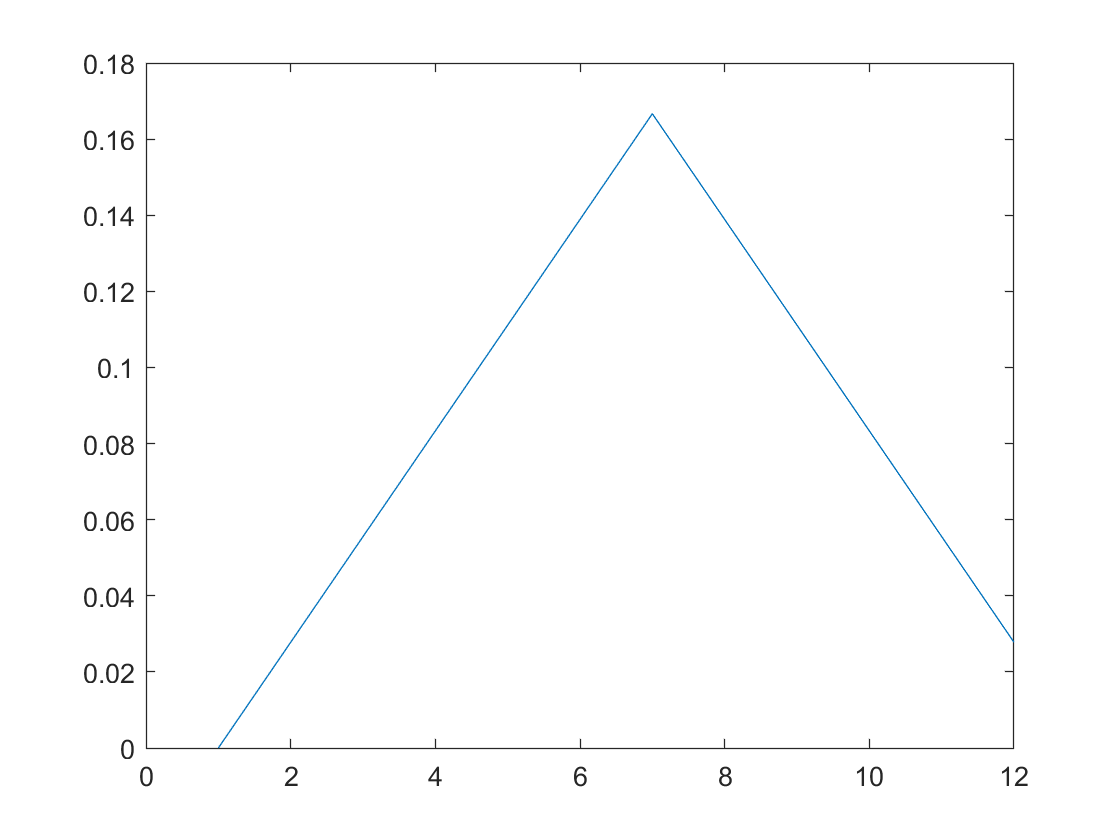

x = 1:12;
plot(uh)


prob_fours = uh(4)

prob_fours = 0.0833

3. Now lets calculate the mean and variance of the dist.

mean_conv = sum(uh.*x)/sum(uh, 'all')

mean_conv = 7.0000


V = var(x,uh)

V = 5.8333

4. Lets graph the average of 10 dice rolls

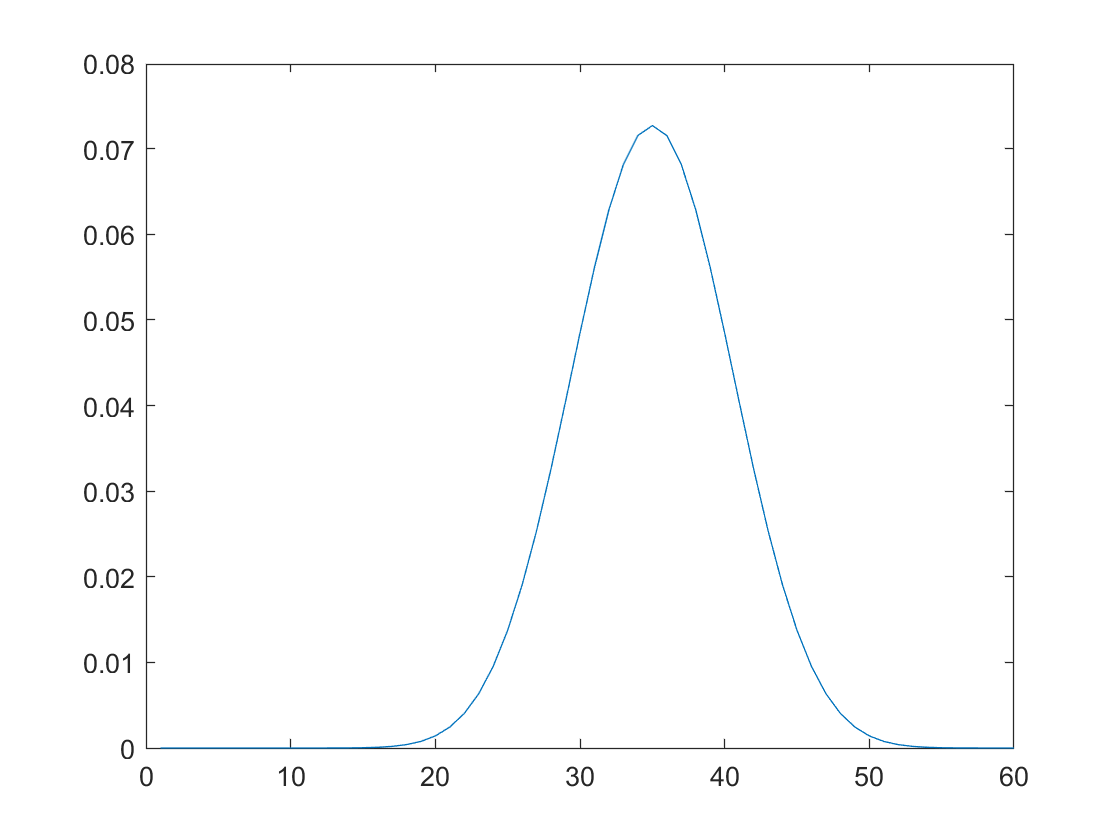

Prob_1 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_2 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_3 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_4 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_5 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_6 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_7 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_8 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_9 = [1/6 1/6 1/6 1/6 1/6 1/6];
Prob_10 = [1/6 1/6 1/6 1/6 1/6 1/6];
uh = zeros(1,60);
uh(1:10) = zeros(1,10);
uh(10:60)=conv(conv(conv(conv(conv(conv(conv(conv(conv(Prob_1, Prob_2), Prob_3), Prob_4), Prob_5), Prob_6), Prob_7), Prob_8), Prob_9), Prob_10);
x = 1:length(uh);
plot(x,uh)


mean_conv = sum(uh.*x)/sum(uh, 'all')

mean_conv = 35.0000

Essentially what we are doing is superimposing ten of the original triangular looking plots on top each other. The more plots you add the more gaussian the distribution will appear to be. 

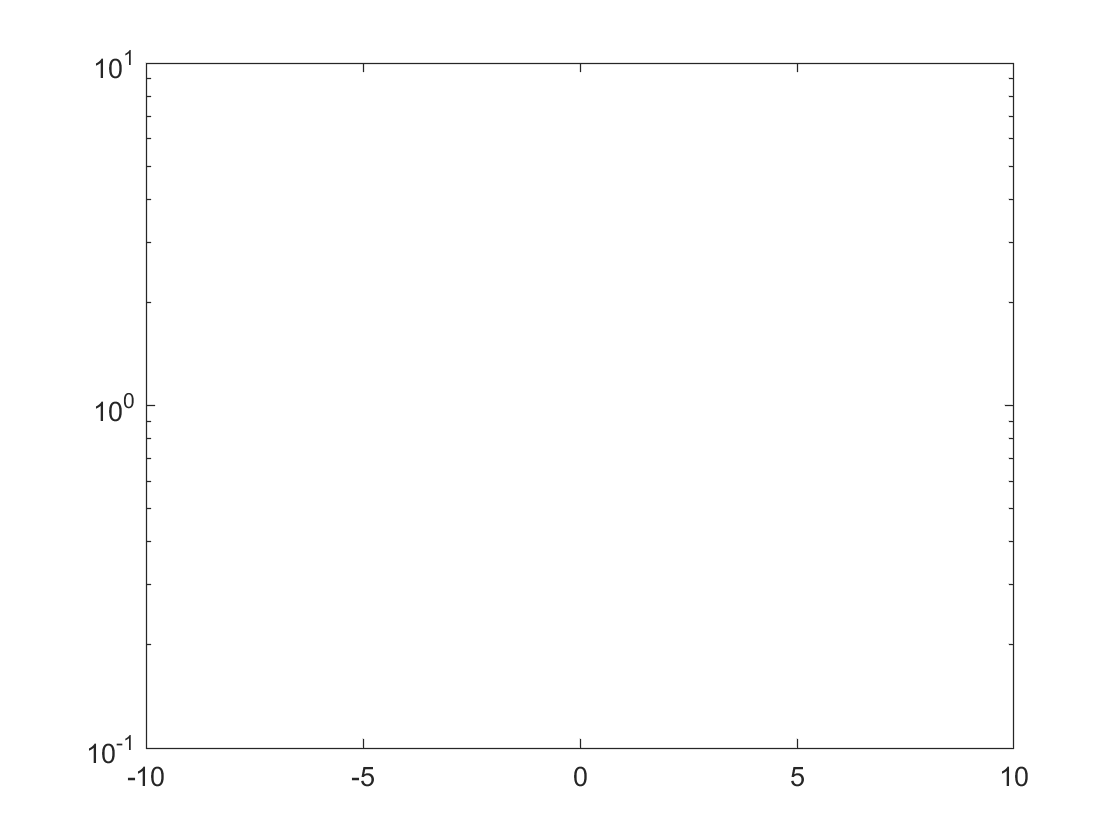


x = linspace(-10,10,1000);
y = linspace(10,-10,1000);
x2 = linspace(-20,20,1999);
sig1 = 10;
mu1 = -1;
gaus1 = makedist("Normal",mu1,sig1);
semilogy(x,pdf(gaus1,x)/pdf(gaus1,x),"LineWidth",4);
hold on

sig2 = 7;
mu2 = 1;
gaus2 = makedist("Normal",mu2,sig2);
%semilogy(x,pdf(gaus2,x)/sum(pdf(gaus2,x)),"LineWidth",4);

sum_gaus = makedist("Normal", mu1+mu2, sqrt(sig1^2+sig2^2));

%semilogy(x2,pdf(sum_gaus,x2)/sum(pdf(sum_gaus,x2)),"LineWidth",4);

conv_gaus = conv(pdf(gaus1,x),pdf(gaus2,x));
sum_conv_gaus = sum(conv_gaus);
%semilogy(x2, conv_gaus/sum_conv_gaus,"LineWidth",4)

ave = (pdf(gaus2,x)+pdf(gaus1,x))./2;

%semilogy(x,ave, "Linewidth", 4)

hold off